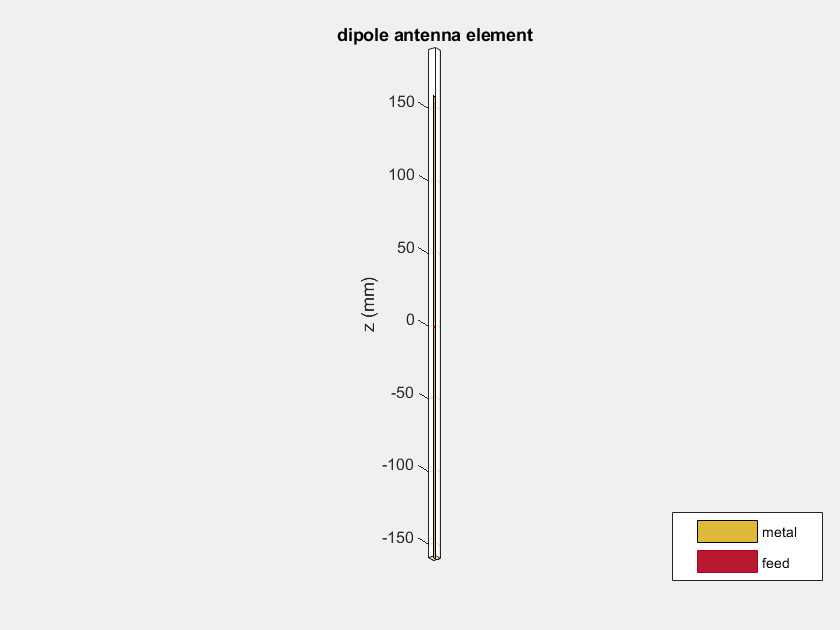

% Create individual element
freq = 450e6;
vp = physconst('lightspeed');
lambda = vp/freq;

N = 4;
var = 0.01;
% inner_radius = 0.063; % 2.5 inches radius
% inner_radius = lambda/8; % 0.0875
inner_radius = lambda/4 - var;
% inner_radius = lambda/4; % = 0.175m

tuning =-0.015;

d = dipole;
d.Length = lambda/2 + tuning;
d.Width = 0.002;
show(d);

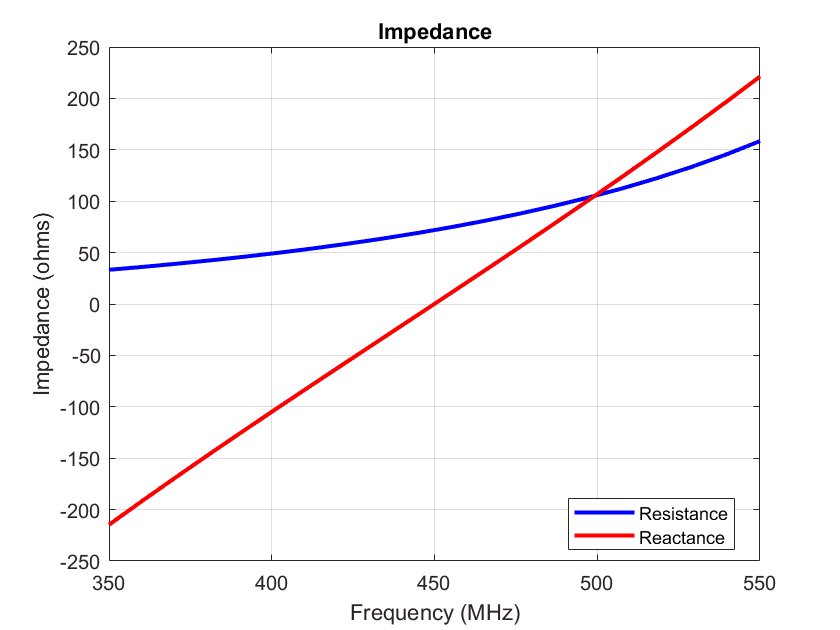

impedance(d,linspace(350e6,550e6,20));

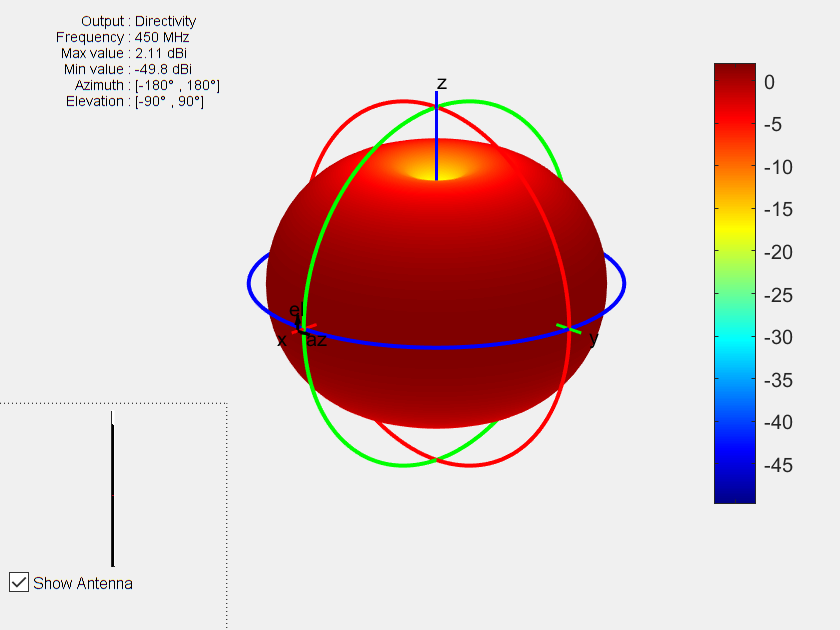

figure;
pattern(d,freq);

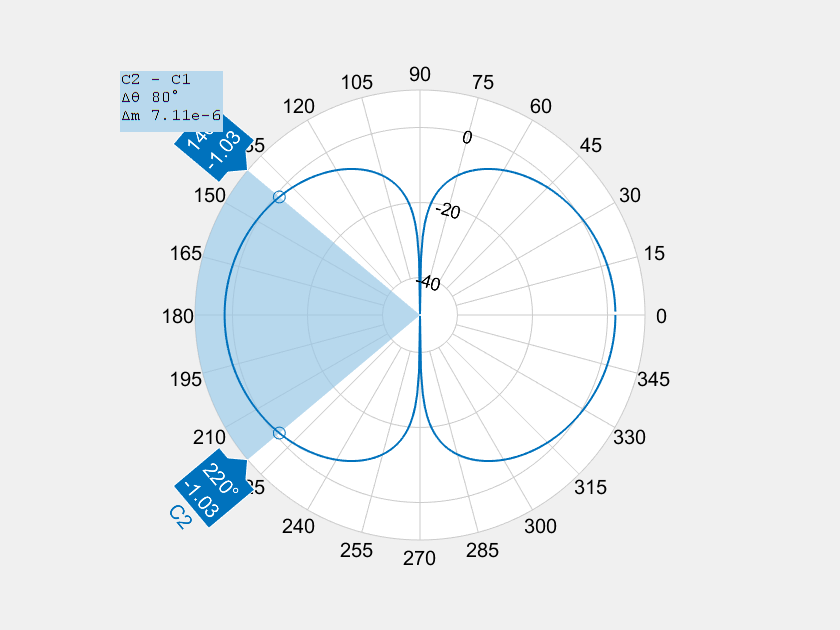

% Plot and calculate beamwidth
figure;
beamwidth(d,freq,0,1:1:360);

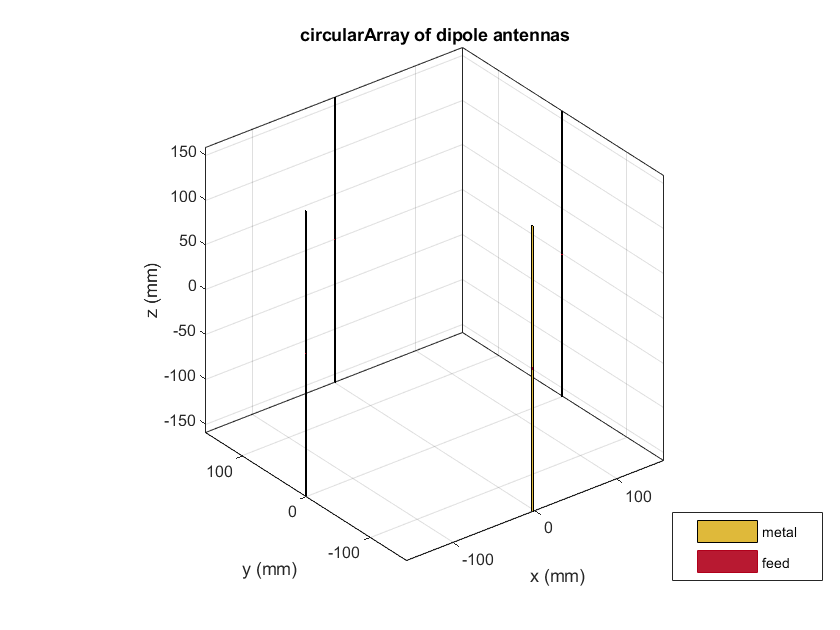

% Create array
dipole_array = circularArray;
dipole_array.Element = d;
dipole_array.NumElements = N;
dipole_array.Radius = inner_radius;
hArray = figure;
show(dipole_array)
axis tight

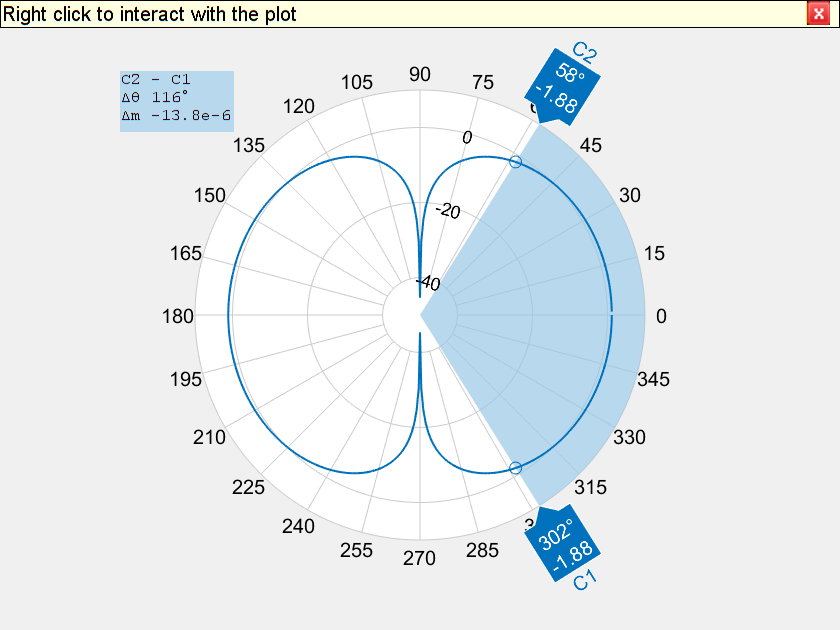

% Plot and calculate beamwidth
figure;
beamwidth(dipole_array,freq,0,1:1:360)

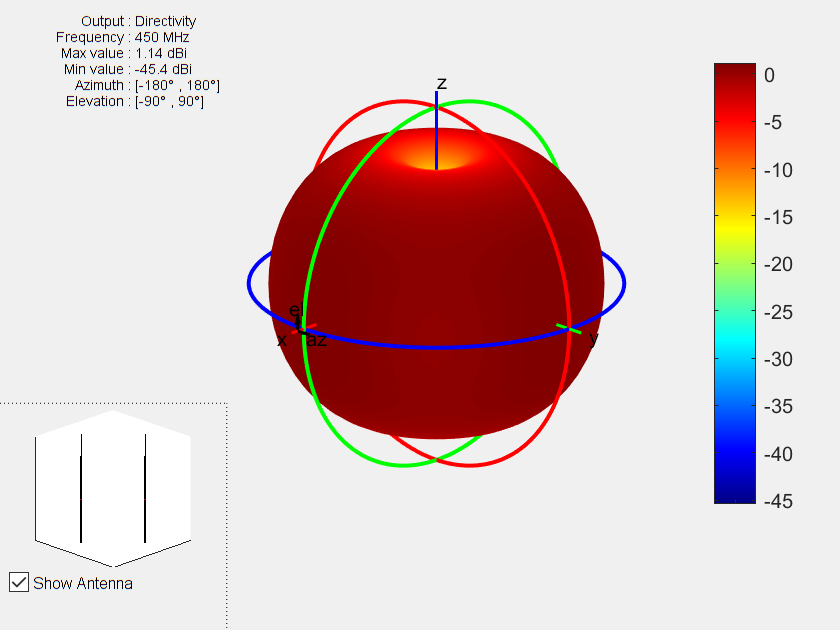

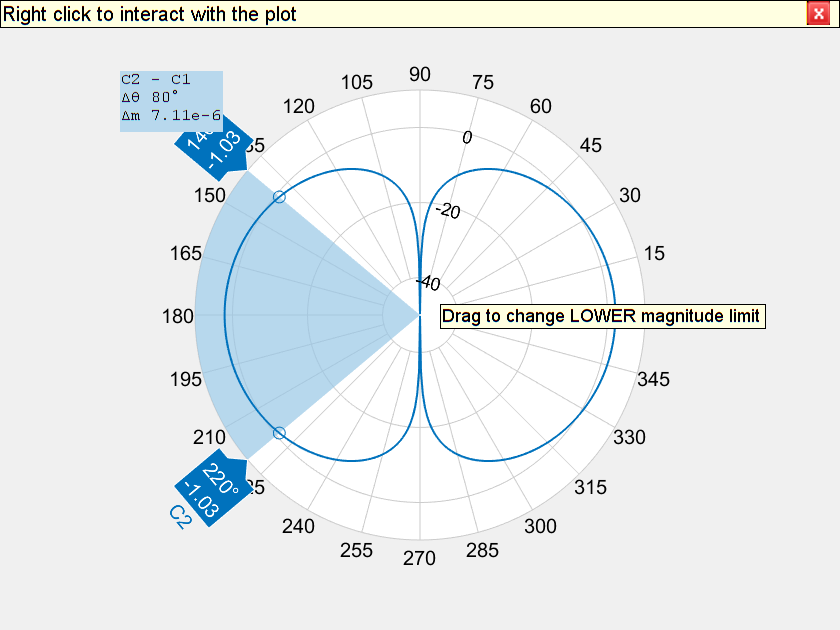

figure;
pattern(dipole_array,freq);